# Coordinate System Transforms

In this notebook we will be working through implementing some of the key ideas behind representing 3D coordinate systems.  Specifically, we'll be thinking about how to represent the relationship between two coordinate systems and how you would update these relationships over time in response to various types of motion.  The exercises you do here will be very helpful in the mapping section of Mount Doom, although you won't necessarily use every single one of the techniques you learn here to the challenge.

## Representing the Relationship Between Two 3D Coordinate Systems

First, let's imagine that we have a coordinate system to represents the QEA classroom (which as we know is the center of the universe).  In order to define our 3D coordinate system, we must first specify a place in the room to serve as our origin. Further, we also must specify the orientations of the room's x, y, and z axes.  We'll refer to this coordinate system as the **room** coordinate system.

Next, let's think about the Neato's body centric coordinate system, which we've discussed several times in this module.  Recall that the origin of this coordinate system is located at the midpoint between the Neato's two wheels with its x-axis pointing forward, y-axis pointing left, and z-axis pointing up.  We'll refer to this as the **robot** coordinate system.  Having two coordinate systems to choose from turns out to be useful.  Many times a calculation that is difficult to perform in one coordinate system may be natural to express in another.  For instance, it may be easier to compute the change in orientation of our Neato in the robot coordinate system and then convert that orientation to the room coordinate system.  Of course, in order to take advantage of this power, we need to have some way to keep track of the relationship beween the room and the robot coordinate systems and update this relationship over time.

To represent the relationship between to coordinate system A and B we specify the position of the origin and orientation of the coordinate axes of coordinate system B in coordinate system A.

To make this more concrete, let's assume the origin of the robot coordinate system is at position (0, 1, 0) in the room frame (we sometimes use the word "frame" instead of "coordinate system").  Further, the robot's x and y-axes are oriented such that they make a 45 degree angle with the respective axes of the room frame.  The z-axes of the room and the robot frame are aligned.  There are many ways to represent the relationship between two coordinate systems, and you'll be learning about more than one before you're done with QEA.  For this module, we will be representing the relationship between two coordinate systems via a translation vector that specifies the position of the origin of the robot's frame in the room frame, and a rotation matrix that specifies the orientation of the Neato's axes in the room frame. 

Here's a MATLAB fragment that defines these two quantities and visualizes the axes.

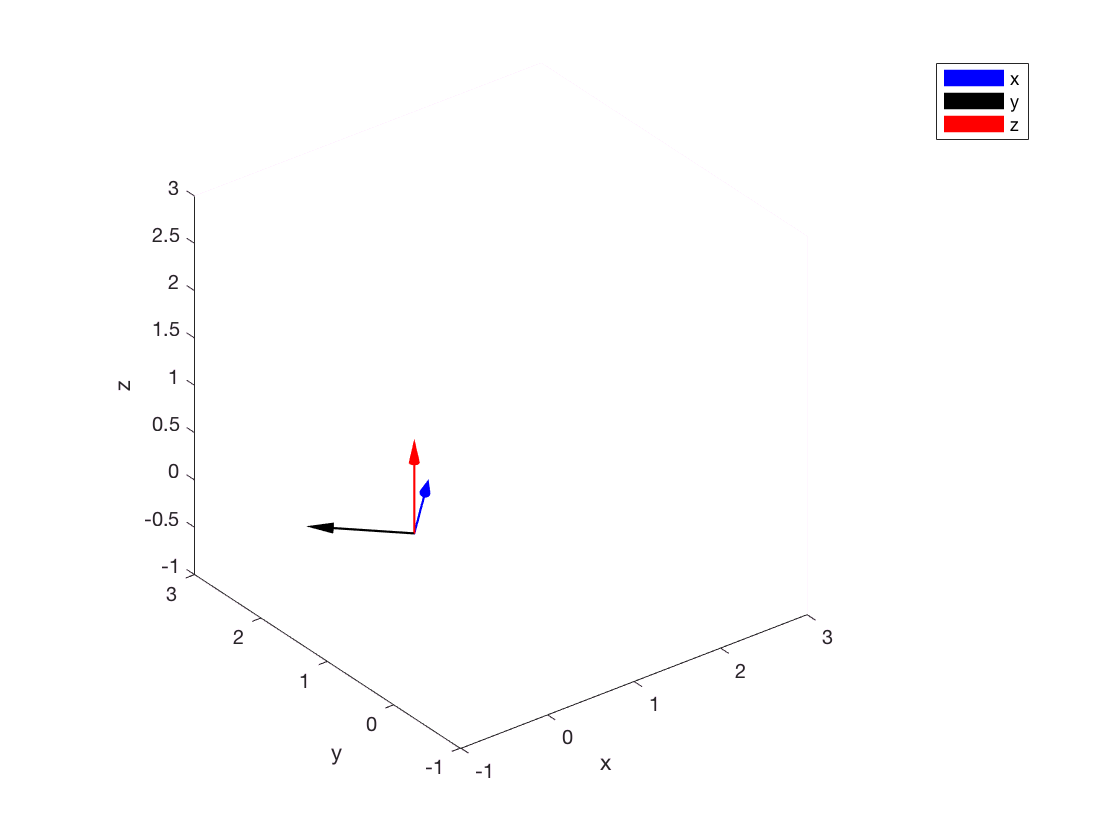

% Remember, orientation represents the direction of
% each of the robot's axes in the room frame.  We can
% see that the first column of 'orientation' makes
% a 45 degree angle with the x-axis of the frame (likewise
% for the y-axis of the robot and the y-axis of the
% room frame.  Further, the z-axes are aligned.
orientation = [cosd(45) -sind(45) 0;...
               sind(45) cosd(45) 0;
               0 0 1];
pos = [0; 1; 0];
visualizeAxes(orientation, pos);

Looking a little closer at the orientation matrix, we see that it has exactly the same form as an elemental rotation about the z-axis by 45 degrees.  Being able to view a rotation matrix as both an operator that can rotate vectors as well as a representation of the axes of a coordinate system turns out to be very powerful.  Additionally, we have a very natural way to think about the position of the robot in the classroom.  Its position is simply the three elements in the vector **pos**.

# Updating the Relationship Between Coordinate Systems

Next, we will work through how to update the relationship between our two coordinate systems in response to various types of motion.

## Translations

Let's start with our robot moving forward a distance of 0.5m.  At the whiteboard draw both the initial and updated coordinate axes of the robot in the room frame.

Once you have developed a prediction for how the coordinate axes should change, write MATLAB code to update the coordinate frame and plot the coordinate axes before and after the transformation.  By default, calling **visualizeAxes** creates a new plot.  If you pass a third argument with the value false, the axes will be drawn directly on the old plot.

visualizeAxes(orientation, pos);

% your solution here

Cool!  We now have a sense of how to handle translations.  What's great is that this technique will work no matter what the orientation of the robot's x-axis in the classroom frame.

What if the robot moved 0.5m in the x-direction in the room frame?   Repeat the previous exercise, but for the case where the movement is in terms of the room frame's axes.  You can use the line of code "[orientation, pos] = resetFrame();" to set the coordinate frame back to what it was before.

[orientation, pos] = resetFrame();
visualizeAxes(orientation, pos);

% your solution here

## Rotations about the Room's Axes

When we talk about rotating about an axis, we need to specify three things: the axis we are rotating about, the angle we are rotating by, and the point in 3d we are rotating around.  For example, suppose our robot rotates by an angle of -15 degrees about the room's y-axis with the center of rotation given by origin of the robot frame (i.e. about the robot's current position).  

Draw pictures of the axes before and after.  To help think through what would happen in this case, determine which of the components of the coordinate system transform (position and orientation) would change as a result of this operation.

Once you have a sketch of the predicted behavior, write code to plot the current coordinate transform, apply the rotation, and plot the updated coordinate axes.

[orientation, pos] = resetFrame();
visualizeAxes(orientation, pos);

% your solution here

What if we now wanted to rotate about one of our robot axes?  Let's think about what would happen if we rotated -15 degrees about the robot's y-axes.  Draw a sketch of the before and after.

Next, write code to apply the transform and plot the before and after.  Recall, that in the Mount Doom challenge writeup you saw a technique for constructing a rotation matrix about an arbitrary axis.  You can use that here to rotate about the robot's current y-axis.  The MATLAB command you will want to check out is **vrrotvec2mat**.

[orientation, pos] = resetFrame();
visualizeAxes(orientation, pos);

% your solution here

## Rotating About Points Other Than the Robot's Origin

Thus far we have been dealing with operations that either changed the orientation or the position of our robot frame but not both.  Once we change the center of rotation to be different than the robot frame's origin (i.e. the robot's position), this will no longer be true.  As an example, what if the robot rotated -45 degrees about the room's z-axis with the center of rotation given by the origin of the *room's* coordinate system?

You know the drill.  Sketch your before and after predictions and implement your result in MATLAB.  Make sure to think about how this transformation would affect each component of the coordinate system relationship (orientation and position).

[orientation, pos] = resetFrame();
visualizeAxes(orientation, pos);

% your solution here

Awesome!  Next, repeat the problem but rotate the coordinate system about the point [-1; -1; 0] in the room frame.  To accomplish this it helps to think about shifting the robot frame's position so that it is in terms of an origin defined by the rotation center, performing the rotation, and then adding the coordinates of the center of rotation to undo the shift you applied in the first step.  Remember to sketch, possibly write out some whiteboard math, and code your answer.

[orientation, pos] = resetFrame();
visualizeAxes(orientation, pos);

% your solution here